# CS283 Assignment 8

Enmao Diao, 2017/11/06

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1

(a)

the BRDF at the surface point imaged at pixel $\vec u$ is $f(λ, \hat w_i(\vec u) ,\hat w_o(\vec u)) = f_d(λ, \vec u)+f_s( \hat w_i(\vec u) ,\hat w_o(\vec u))  $

and the spectral sensitivities  is $c(\lambda) = (c_R(\lambda),c_G(\lambda) ,c_N(\lambda) )$, the illuminant spectrum  (blackbody radiation) is $e(\lambda)$

Thus the color RGB value 


$$\vec C(\vec u) = \int c(\lambda)f(λ, \hat w_i(\vec u) ,\hat w_o(\vec u))e(\lambda)d\lambda$$



$$= \int c(\lambda)f_d(λ, \vec u) e(\lambda)d\lambda + f_s(\hat w_i(\vec u) ,\hat w_o(\vec u))\int c(\lambda)e(\lambda)d\lambda$$



$$=<\hat n(\vec u), \hat l>\vec d(\vec u) + g_s(\vec u)\vec s$$


Thus, since $<\hat n(\vec u), \hat l>$ is a constant and $g_s(u)$ is a function that depends non-linearly on $\hat n(\vec u)$ (as well as view and lighting directions) through the specular component of the BRDF


$$d(\vec u) =\frac{\int c(\lambda)f_d(λ, \vec u) e(\lambda)d\lambda}{<\hat n(\vec u), \hat l>} $$



$$\vec s = \int c(\lambda)e(\lambda)d\lambda$$


(b)

(i)


$$\vec J(\vec u) = (<\hat r_1, \vec C(\vec u)>,<\hat r_2, \vec C(\vec u)>)$$



$$<\hat r_1, \vec C(\vec u)> =  <\hat r_1, <\hat n(\vec u), \hat l>\vec d(\vec u)> + <\hat r_1, g_s(\vec u)\vec s>$$


since $ g_s(\vec u) = f_s(\hat w_i(\vec u) ,\hat w_o(\vec u))$ is a constant and $\vec r_1$ and $\vec s$ are orthogonal to each other


$$<\hat r_1, g_s(\vec u)\vec s> = 0$$



$$<\hat r_1, \vec C(\vec u)> =  <\hat r_1, <\hat n(\vec u), \hat l>\vec d(\vec u)> $$


This is also true for $<\hat r_2, \vec C(\vec u)>$. Therefore, $\vec J(\vec u)$does not depend on the specular components  $g_s(\vec u) =  f_s(\hat w_i(\vec u) ,\hat w_o(\vec u))$

(ii)


$$<\hat r_1, \vec C(\vec u)> =  <\hat r_1, <\hat n(\vec u), \hat l>\vec d(\vec u)>$$


Since $<\hat n(\vec u), \hat l>$ is a constant,


$$=\hat r_1^T (\hat n(\vec u)^T\hat l\vec d(\vec u)) = \hat n(\vec u)^T\hat l\hat r_1^T \vec d(\vec u)$$



$$ = <\hat n(\vec u), \hat l\hat r_1^T \vec d(\vec u)>$$


Thus $<\hat r_1, \vec C(\vec u)>$ linearly depends on $\hat n(\vec u)$. This is also true for $<\hat r_2, \vec C(\vec u)>$

Thus $\vec J(\vec u)$ linearly depends on $\hat n(\vec u)$

(c)

For L2 norm $||\vec J(\vec u)||$

We have 


$$||\vec J(\vec u)|| = \sqrt{<\vec J(\vec u),\vec J(\vec u)>}$$


(i)

 We also have $<\hat r_1, g_s(\vec u)\vec s> = 0$. Thus $\vec J(\vec u)$does not depend on the specular components  $g_s(\vec u) =  f_s(\hat w_i(\vec u) ,\hat w_o(\vec u))$


$$<\hat r_1, \vec C(\vec u)> =  <\hat r_1, <\hat n(\vec u), \hat l>\vec d(\vec u)> $$



$$\vec J(\vec u) = (<\hat r_1, \vec C(\vec u)>,<\hat r_2, \vec C(\vec u)>)$$



$$||\vec J(\vec u)|| = \sqrt{<\hat r_1, \vec C(\vec u)><\hat r_1, \vec C(\vec u)>+<\hat r_2, \vec C(\vec u)><\hat r_2, \vec C(\vec u)>}$$



$$= \sqrt{\hat r_1^T (\hat n(\vec u)^T\hat l\vec d(\vec u))\hat r_1^T (\hat n(\vec u)^T\hat l\vec d(\vec u))+\hat r_2^T (\hat n(\vec u)^T\hat l\vec d(\vec u))\hat r_2^T (\hat n(\vec u)^T\hat l\vec d(\vec u))}$$


It is also clear that its norm $||\vec J(\vec u)||$ does not depend on $f_s(\hat w_i(\vec u) ,\hat w_o(\vec u))$

(ii)


$$||\vec J(\vec u)||  = \sqrt{\hat n(\vec u)^T\hat l\hat r_1^T \vec d(\vec u)\hat n(\vec u)^T\hat l\hat r_1^T \vec d(\vec u)+\hat n(\vec u)^T\hat l\hat r_2^T \vec d(\vec u)\hat n(\vec u)^T\hat l\hat r_2^T \vec d(\vec u)}$$



$$=\hat n(\vec u)^T\hat l \vec d(\vec u)\sqrt{\hat r_1^T\hat r_1+\hat r_2^T\hat r_2}$$


since $\sqrt{\hat r_1^T\hat r_1+\hat r_2^T\hat r_2}$ is a constant

$||\vec J(\vec u)||$ linearly depends on $\hat n(\vec u)$

(d)

*imout* smooths the large values or flashes induced by the reflectance of the object. It is more useful than *im* for a computer vision system because those large values are created mostly by the camera instead of only the object itself and therefore yields not much useful information or perhaps some noises to interpret the actual object.

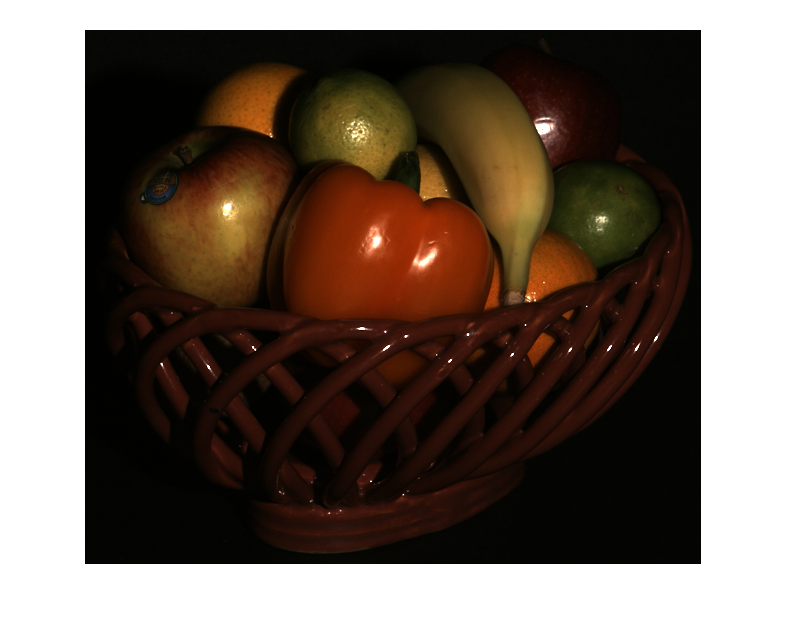

im=im2double(imread('./data/fruitbowl.png'));
figure
imshow(min(1,im./0.1));

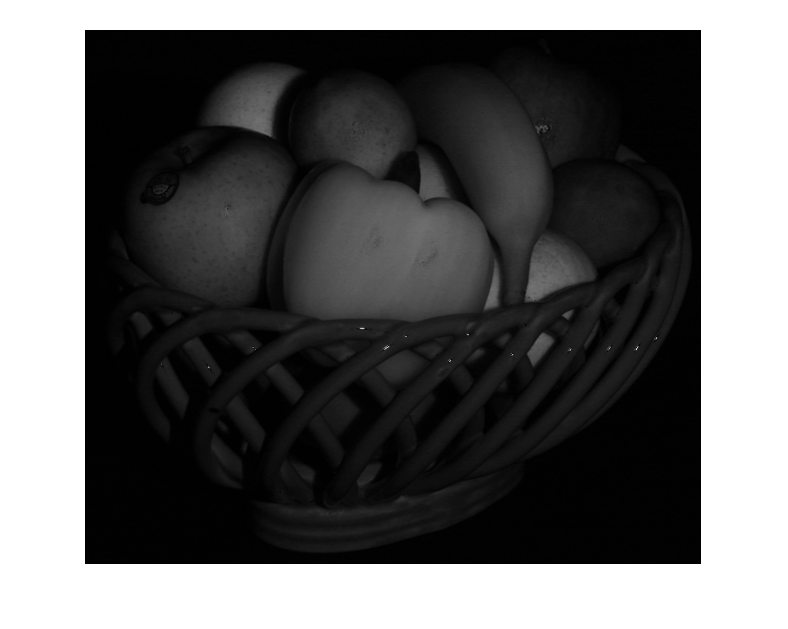

s = [0.6257 0.5678 0.5349];
imout = makeLambertian(im, s);
figure
imshow(min(1,imout./0.1));

# Question 2

(a)

Since spectral radiance = spectral reflectance * illuminant spectrum

spectral reflectance = $f(\lambda)$ and $g(\lambda)$

illuminant spectrum =  $l(\lambda)$

the tristimulus vector  $\vec C_f = (X_f,Y_f,Z_f) = \int Rf(\lambda)l(\lambda)d\lambda$


$$=(\int R_x \circ f(\lambda)^Tl(\lambda)d\lambda,\int R_y \circ f(\lambda)^Tl(\lambda)d\lambda,\int R_z \circ f(\lambda)^Tl(\lambda)d\lambda)$$



$$=L_f\vec l$$


where $L_f = (R_x \circ f(\lambda)^T,R_y \circ f(\lambda)^T,R_z \circ f(\lambda)^T)$ and $R_x$, $R_y$, $R_z$ are the 1st, 2nd and 3rd rows of $R$

$\vec l $ is the discretization of $l(\lambda)$, $\circ$ denots Hadamard product 

(b) 

Two resulting tristimulus vectors $\vec C_f$ and $\vec C_g$

from (a) we know

$\vec C_f = L_f\vec l$, $\vec C_g = L_g\vec l$

The L2 distance is 


$$D = ||\vec C_f-\vec C_g||_2$$



$$= ||L_f\vec l - L_g\vec l||_2$$



$$= ||(L_f- L_g)\vec l||_2$$


(c)

For each grid value of temperature of  [2500K:50K:10000K], we compute the L2 distance from (b). We return the temperature that yields the minimum distance.

We normalize the spectral power distributions of blackbody radiators  with its maximum value at each temperature

We plot the L2 distance with respect to the temperature and the spectral power distributions at the best temperature

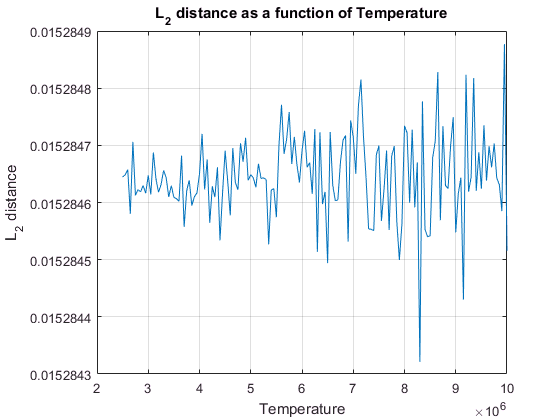

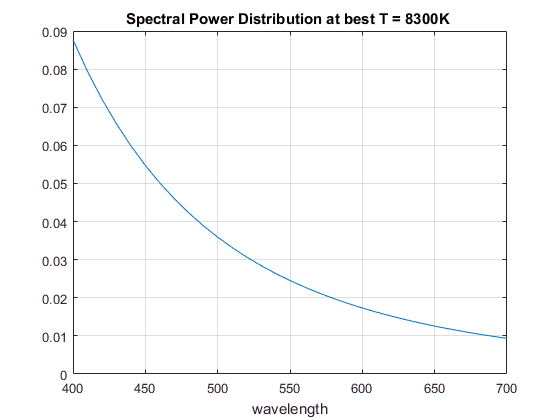

load('./data/bananas.mat');
T = metamericLight(ripe,overripe);

# Question 3

(a)

Following the hint, we compute wSSD with proper 2d convolution. We clip the numerical error for wSSD to be at least be nonnegative. Insize *conv2(A,B,'valid')*, we flip B matrix and set A always assciosted with either $w_1$ or sourceimage.

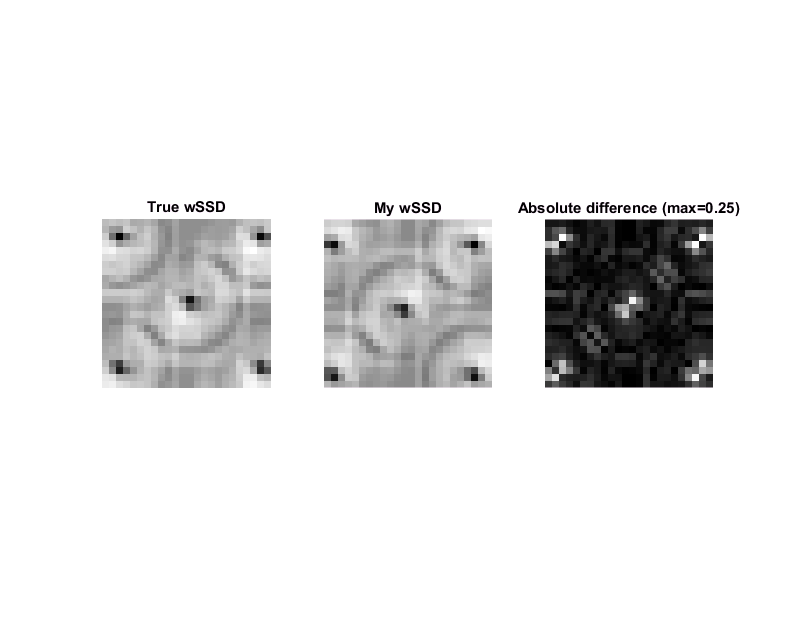

% Load test data. Variables are:
%   sourceimage  = 34x34 source texture image (rings.jpg)
%   targetwindow = 11x11 target window to be matched
%   validmask    = 11x11 binary matrix
%   G            = 11x11 Gaussian kernel
%   gt_wSSD      = 24x24 "ground truth" weighted SSD for comparison
load('./data/testFindMatches.mat');

% Replace this line with your wSSD code, which will form the core of your 
%  function FindMatches. Your wSSD code here should produce a 24x24 map of 
%  wSSD scores (same size as the source texture image), and it should do 
%  so without using loops. Instead of loops you should use appropriate 
%  calls to conv2(...,'valid').
[~, mywSSD]=FindMatches(targetwindow, validmask, sourceimage, G);

% compare
if size(mywSSD)~=size(gt_wSSD)
    error(['My wSSD is not 24x24 as expected']);
end

% compare your wSSD map beside the ground truth. You want the 
%  right-most "Absolute difference" map to be filled with zeros. It 
%  should say "(max=0)" in the title.  
figure(1); clf;
subplot(1,3,1); imshow(gt_wSSD,[]); title 'True wSSD';
subplot(1,3,2); imshow(mywSSD,[]); title 'My wSSD';
subplot(1,3,3); imshow(abs(gt_wSSD-mywSSD),[]); 
title(sprintf('Absolute difference (max=%0.2g)',max(abs(gt_wSSD(:)-mywSSD(:)))));

(b)

We initialize the image with size *synthdim. *We first find the corresponding neighbourhood from the seed patch with *imdilate* and *find.*

We choose to update the value of pixels which have the most number of already filled pixels first. We also take care of the boundary condition.

Then the candidate pixels are generated from *FindMatches()*. We randomly sample one of them and validate it with a threshold.

We iteratively conduct above steps untill we fill all the pixels. We gradually increase the max error threshold if we get stuck.

(c)

We achieve stable and best performance when window size = 13. Actually increasing or decreasing the window size will degrade the performance. For window size 5 and 7 as shown in following figures, rerunning the algorithm will yield different results. We get a stable result for window size 13 as shown in the following figures. The reason is that small window size does not cover the whole ring and large window size will have overlapped rings. This may suggest that we should use a window size that cover the minimum element in the template.

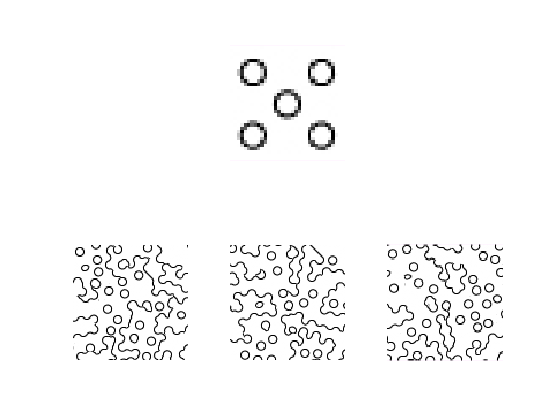

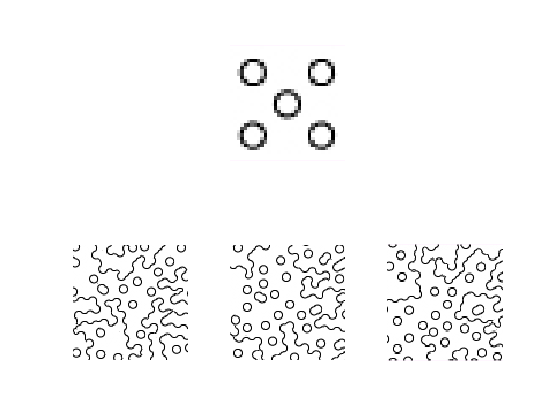

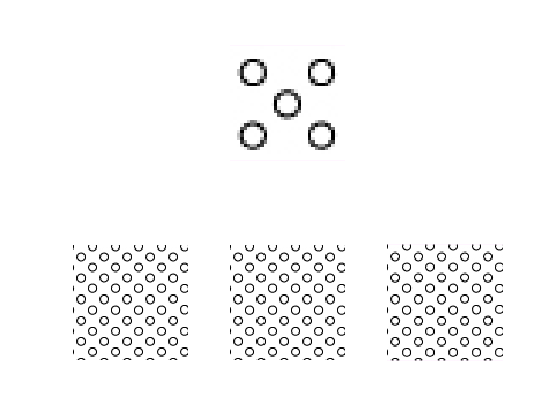

All functions in a script must be closed with an 'end'.


sourceimage = im2double(imread('./data/rings.jpg'));
synthdim= [100 100];
ws = [5 7 13];
figure
subplot(2,3,2)
imshow(sourceimage); 
for i=1:length(ws)
    for j=1:3
        synthim = SynthTexture(sourceimage, ws(i), synthdim);
        subplot(2,3,3+j)
        imshow(synthim); 
    end
end

# Local Functions

function imout = makeLambertian(im, s)
    %% 1(d)
    r = null(s);
    r1 = r(:,1);
    r2 = r(:,2);
    [a,b,~] = size(im);
    J = zeros([a,b,2]);
    J_norm = zeros([a,b,1]);
    for i = 1:a
        for j = 1:b
            J(i,j,1) = r1'*squeeze(im(i,j,:));
            J(i,j,2) = r2'*squeeze(im(i,j,:));
            J_norm(i,j,1) = norm([J(i,j,1),J(i,j,2)]);
        end
    end
imout =  J_norm;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 2(c)
function T = metamericLight(f,g)
cmf = csvread('./data/ciexyz64_1.csv');
init_lambda = 400;
end_lambda = 700;
space_lambda = 10;
lambdas = init_lambda:space_lambda:end_lambda;
idx = find(cmf(:,1)==init_lambda);
R = cmf(idx:space_lambda:idx+(end_lambda-init_lambda),2:4)';
a = 1.4388e-2;
L_T = @(T) 1./lambdas.^5.*1./(exp(a./(lambdas.*T))-1);
Ts = 2500e3:50e3:10000e3;
D = zeros(1,length(Ts));
for i = 1:length(Ts)
    SPD = (L_T(Ts(i))./sum(L_T(Ts(i))))';
    tmpf = R.*repmat(f',[3,1])*SPD;
    tmpg = R.*repmat(g',[3,1])*SPD;
    D(i)=norm(tmpf- tmpg);
end
[~,idic] = min(D);
T=Ts(idic);
figure
plot(Ts,D)
grid on
title('L_2 distance as a function of Temperature')
xlabel('Temperature')
ylabel('L_2 distance')
figure
plot(lambdas,L_T(T)./sum(L_T(T)))
grid on
title(sprintf('Spectral Power Distribution at best T = %dK ',T/1000))
xlabel('wavelength')
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 3(a)
function [pixvalues, matcherrors] = FindMatches(targetwindow, validmask, sourceimage, G)
errthresh = 0.1;
w0 = validmask.*G; 
w0=w0/sum(w0(:)); 
w1 = ones(size(sourceimage));
matcherrors =  conv2(w1,rot90(w0 .* targetwindow.^2,2),'valid')-2*conv2(w1 .* sourceimage,rot90(w0 .* targetwindow,2),'valid') + conv2(w1.* sourceimage.^2,rot90(w0,2),'valid');
pixvalues = matcherrors<= max([0,min(matcherrors(:))])*(1+errthresh);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 3(b)
function synthim = SynthTexture(sourceimage, w, synthdims)
maxerrthresh = 0.3;
seedsize = 3;
targetimage = zeros(synthdims);
seedpatch = sourceimage(5:7,4:6);
[imagesizex,imagesizey] = size(sourceimage);
halfwindow = (w-1)/2;
imagesizecentered = [(imagesizex - w + 1) (imagesizey - w + 1)];
seedrows = ceil(synthdims(1)/2)-ceil(seedsize/2)+1:ceil(synthdims(1)/2)+(seedsize-ceil(seedsize/2));
seedcols = ceil(synthdims(2)/2)-ceil(seedsize/2)+1:ceil(synthdims(2)/2)+(seedsize-ceil(seedsize/2));
targetimage(seedrows,seedcols) = seedpatch;
nfilled = seedsize * seedsize;
nfailed = 0; 
npixels = prod(synthdims);
G = fspecial('gaussian',w, w/6.4);
filled = false(synthdims); 
filled(seedrows, seedcols) = true;
while nfilled < npixels
    stuck =false;
    SE = strel('square',w);
    neighbour_bool = imdilate(filled,SE)-filled;
    [neighbourrow, neighbourcol] = find(neighbour_bool);
    filledcounts = colfilt(filled, [w w], 'sliding', @sum); 
    num_filled_neighbors = filledcounts(sub2ind(size(filled),neighbourrow, neighbourcol)); 
    [~, sortindex] = sort(num_filled_neighbors, 1, 'descend');    
    neighbourrow = neighbourrow(sortindex); 
    neighbourcol = neighbourcol(sortindex); 
    for i = 1:length(neighbourrow)
        pixelrow = neighbourrow(i);
        pixelcol = neighbourcol(i);       
        rowspan = pixelrow-halfwindow:pixelrow+halfwindow;
        colspan = pixelcol-halfwindow:pixelcol+halfwindow;
        rowbound = rowspan < 1 | rowspan > synthdims(1);
        colbound = colspan < 1 | colspan > synthdims(2); 
        if any(rowbound)||any(colbound) 
            saferow = rowspan(~rowbound); 
            safecol = colspan(~colbound); 
            temp = zeros(w, w); 
            temp(~rowbound, ~colbound) = targetimage(saferow, safecol); 
            validmask = false([w w]); 
            validmask(~rowbound, ~colbound) = filled(saferow, safecol); 
        else
            temp = targetimage(rowspan, colspan);
            validmask = filled(rowspan, colspan); 
        end  
        [pixvalues, matcherrors] = FindMatches(temp, validmask, sourceimage, G);
        matchidx = find(pixvalues);
        perm = randperm(length(matchidx));
        matchidx_sampled = matchidx(perm(1));
        matcherror = matcherrors(matchidx_sampled);
        if matcherror < maxerrthresh 
            [matchrow, matchcol] = ind2sub(imagesizecentered, matchidx_sampled);
            matchrow_corrected = matchrow + halfwindow;
            matchcol_corrected = matchcol + halfwindow;
            targetimage(pixelrow, pixelcol) = sourceimage(matchrow_corrected, matchcol_corrected);
            filled(pixelrow, pixelcol) = true;  
            nfilled = nfilled + 1; 
        else
            stuck = true;
            nfailed = nfailed + 1; 
        end
    end
    if(stuck)
        maxerrthresh= maxerrthresh*1.1;
    end
end
synthim = targetimage;
end
